## DNA Base Composition

DNA is made up of four nucleotide bases: **A (Adenine), T (Thymine), G (Guanine), and C (Cytosine)**. In this example, we will analyze a short DNA sequence by counting the number of times each base appears.

Say, we are given the following DNA sequence:

`ATGCGATCGATCGATTTAGC`

sequence = 'ATGCGATCGATCGATTTAGC';
disp(sequence)

ATGCGATCGATCGATTTAGC


The `sum` function allows us to easily sum over an array. But for that, we need an array!

base_A_arr = sequence == 'A' % Notice that I am skipping the semicolon

base_A_arr = 1×20 logical array
   1   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0


We can sum over this array

sum(base_A_arr)

ans = 5

### We can combine these in a few lines

A = sum(sequence == 'A');
T = sum(sequence == 'T');
G = sum(sequence == 'G');
C = sum(sequence == 'C');

counts = [A T G C];
disp(counts)

     5     6     5     4



### And we can plot them in a histogram!

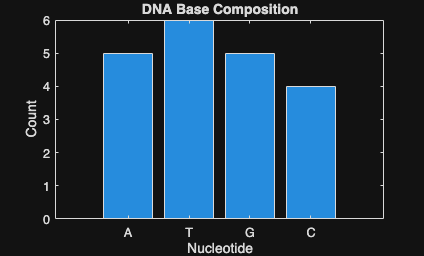

bar(counts)

xticklabels({'A','T','G','C'})
xlabel('Nucleotide')
ylabel('Count')
title('DNA Base Composition')

### And of course, we can print them out

fprintf('A: %d\n', A);

A: 5


fprintf('T: %d\n', T);

T: 6


fprintf('G: %d\n', G);

G: 5


fprintf('C: %d\n', C);

C: 4
